# RSA analysis

clear;
clc;
close all;
load('project_params.mat');
excludeSubjects();

ans =   Map with properties:

        Count: 45
      KeyType: char
    ValueType: any


## 1. Extract RDMs per ROI

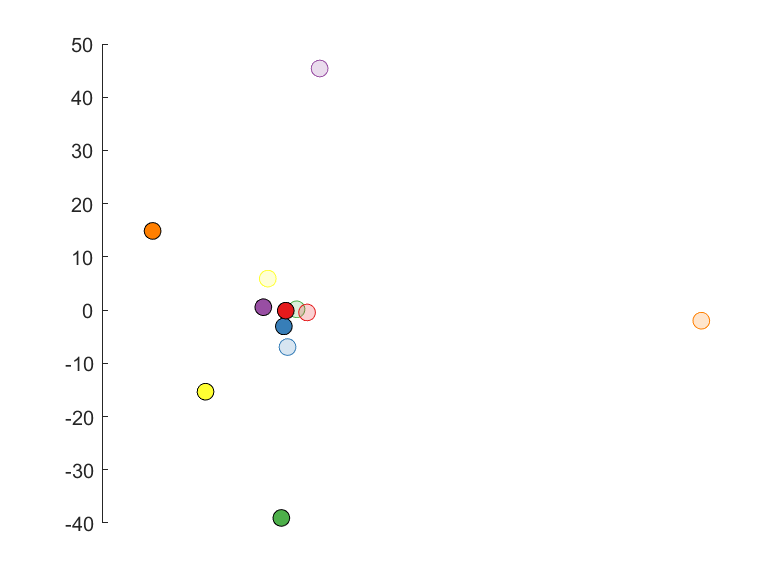

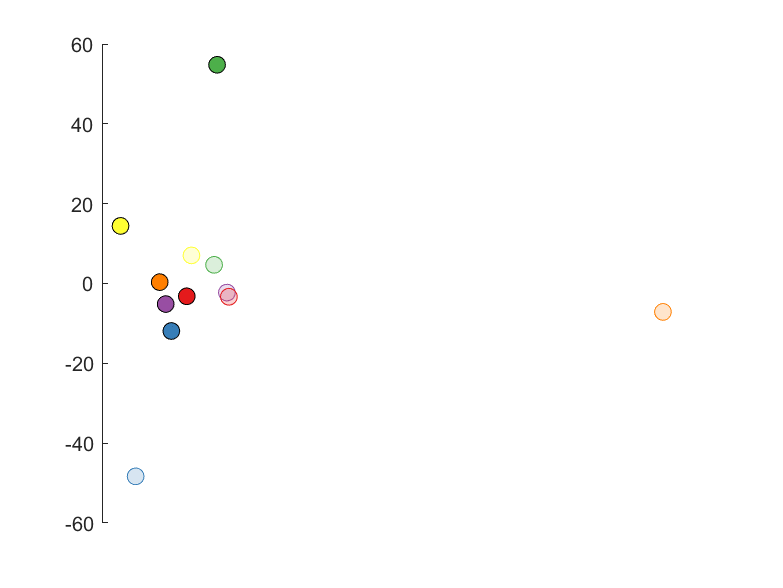

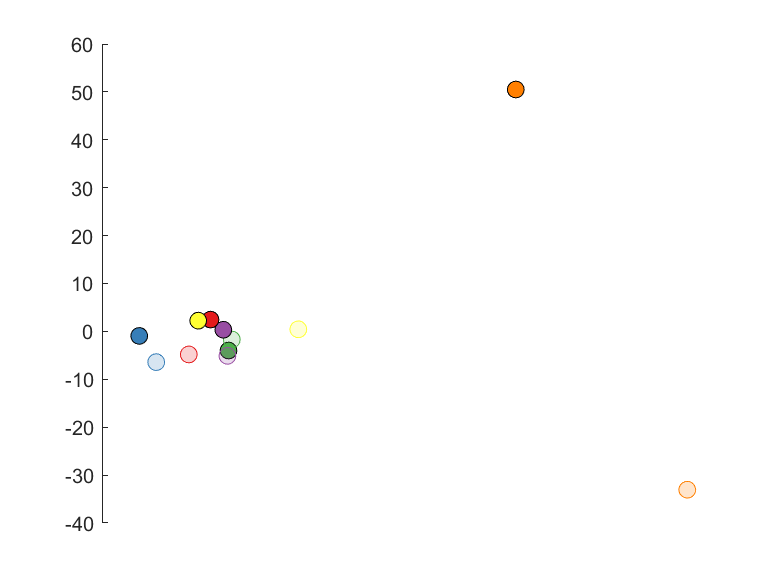

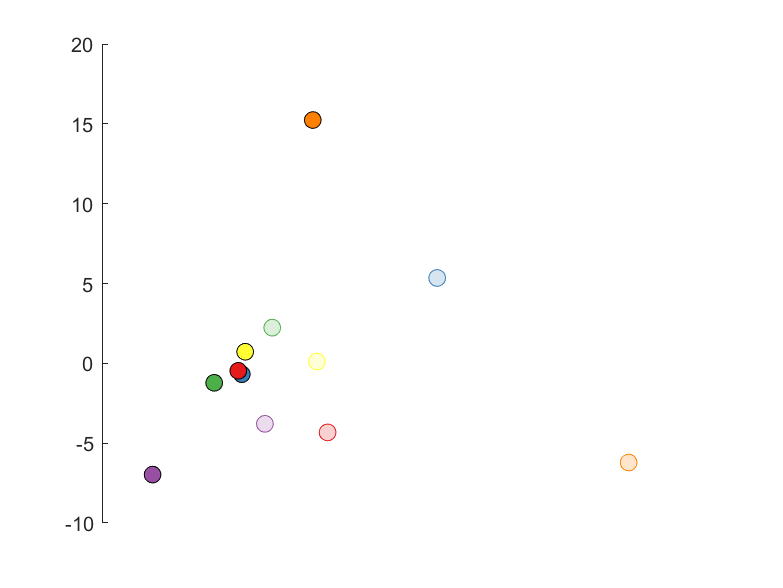

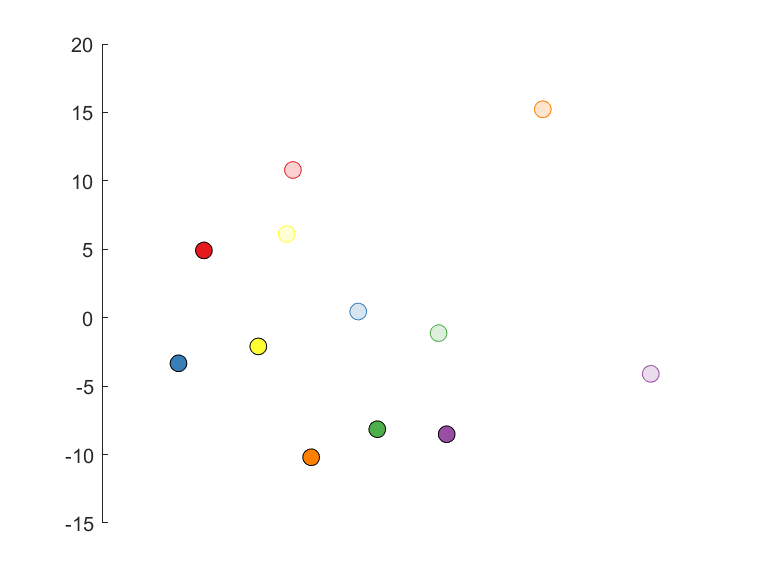

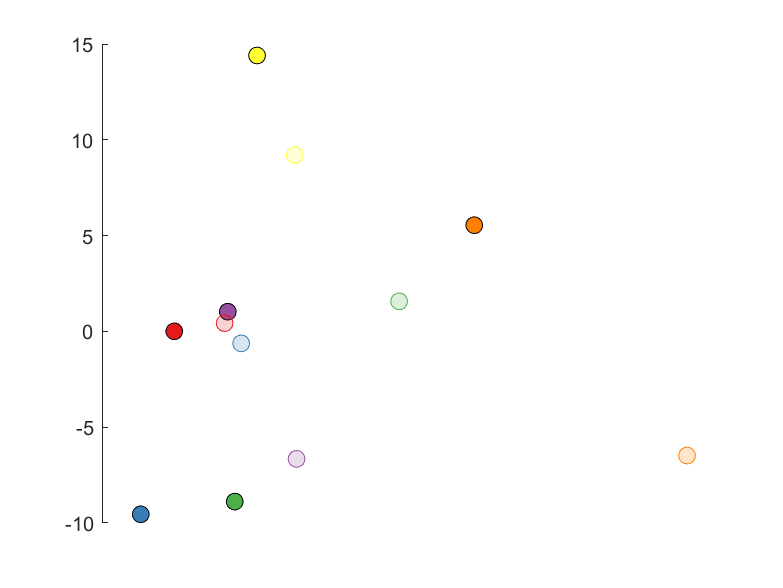

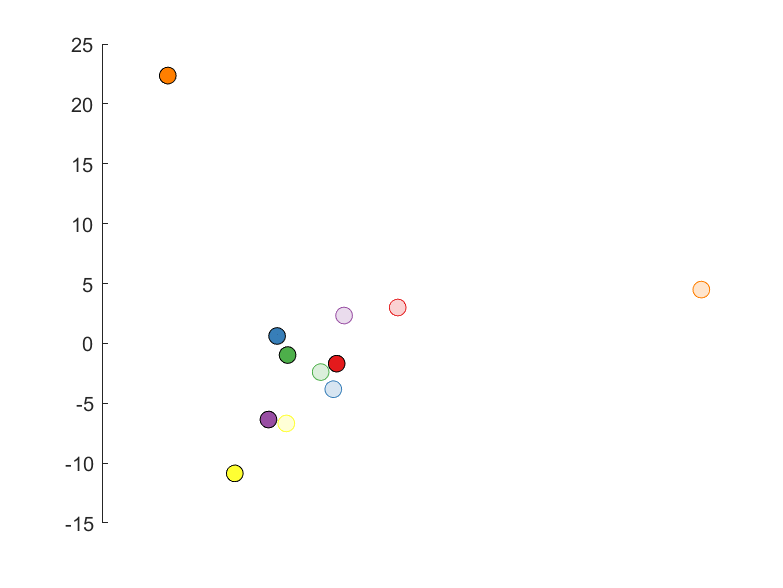

BOLD2RDMFromROI(project_params,which_subjects,'euclidean')

## 2. Quality check: compare on and off diagonals

compareOnOffDiagonals(project_params,which_subjects,'euclidean')

ROI = 'FPl'

h = 0

p = 0.1793

ci =    -3.8682
    0.7513


stats = struct with fields:
    tstat: -1.3712
       df: 34
       sd: 6.7238


ROI = 'FPm'

h = 1

p = 0.0023

ci =    -5.5300
   -1.3064


stats = struct with fields:
    tstat: -3.2894
       df: 34
       sd: 6.1477


ROI = 'BA46'

h = 1

p = 0.0071

ci =    -6.0725
   -1.0340


stats = struct with fields:
    tstat: -2.8664
       df: 34
       sd: 7.3337


ROI = 'vmPFC'

h = 1

p = 0.0472

ci =    -6.4512
   -0.0423


stats = struct with fields:
    tstat: -2.0591
       df: 34
       sd: 9.3286


ROI = 'rTPJ'

h = 0

p = 0.2286

ci =    -6.8334
    1.6906


stats = struct with fields:
    tstat: -1.2261
       df: 34
       sd: 12.4071


ROI = 'rSTS'

h = 1

p = 0.0373

ci =    -7.4395
   -0.2385


stats = struct with fields:
    tstat: -2.1668
       df: 34
       sd: 10.4814


ROI = 'preSMA'

h = 0

p = 0.1979

ci =    -4.7511
    1.0212


stats = struct with fields:
    tstat: -1.3132
       df: 34
       sd: 8.4020


## 3. Compare empirical and theoretical RDMs

ROI = 'FPl'

ROI = 'FPm'

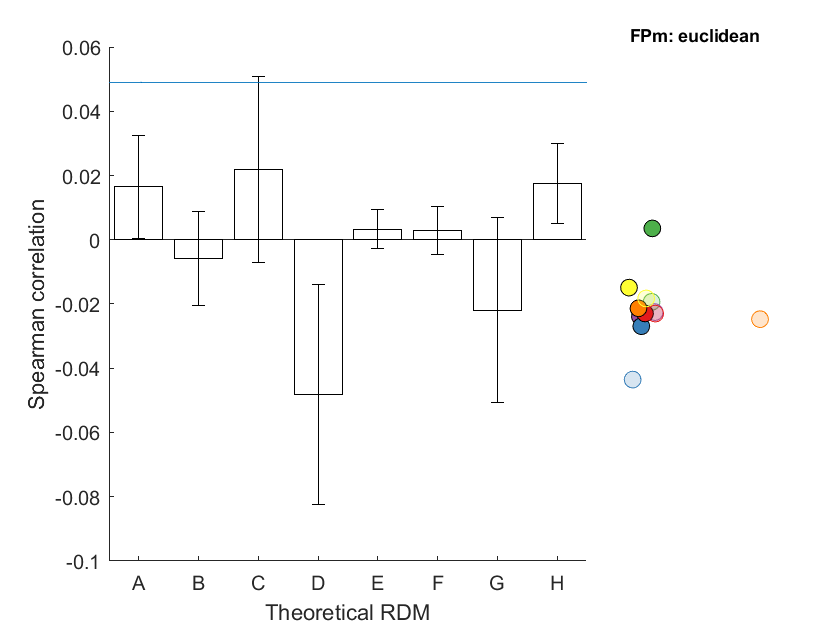

ROI = 'BA46'

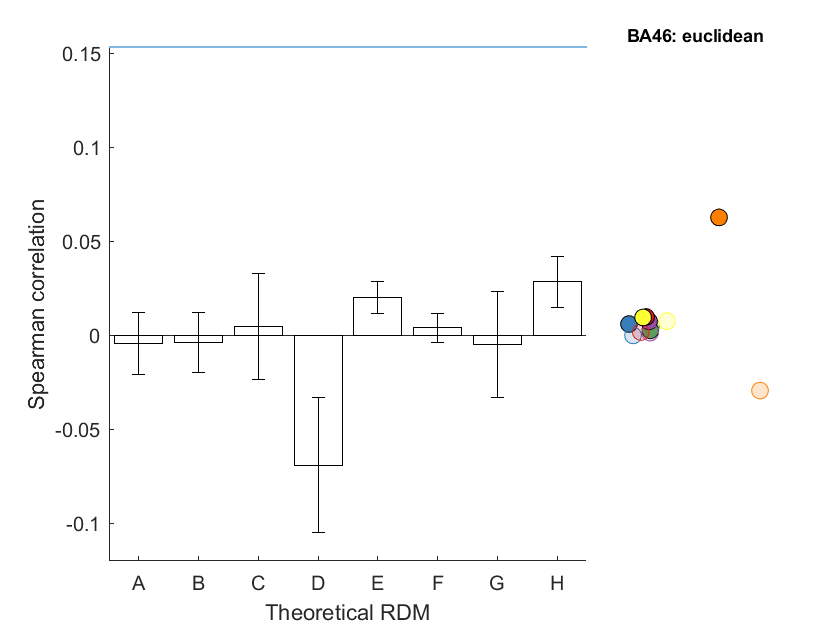

ROI = 'vmPFC'

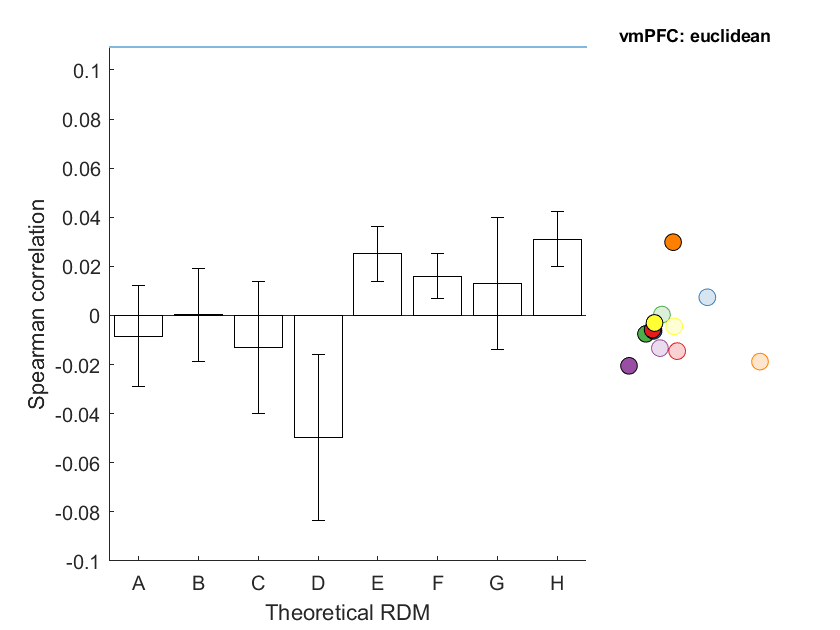

ROI = 'rTPJ'

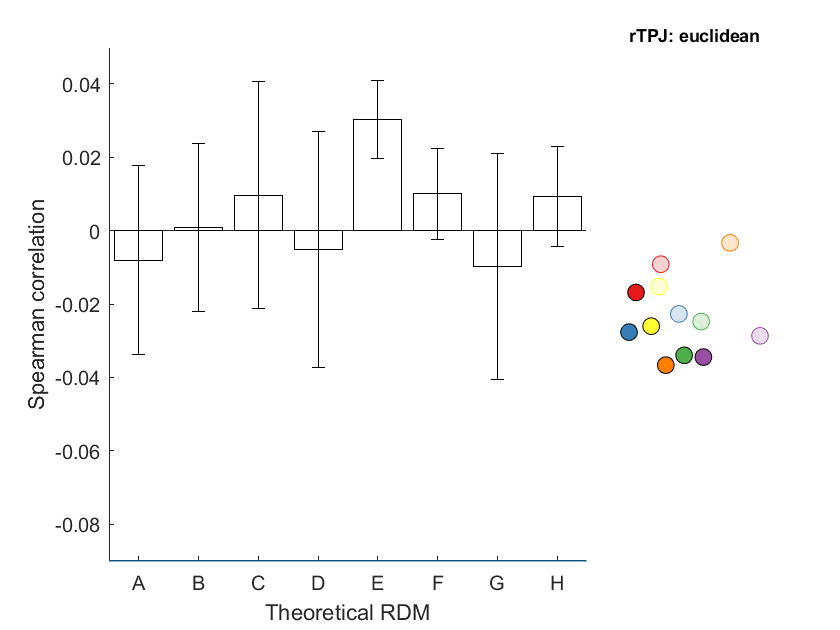

ROI = 'rSTS'

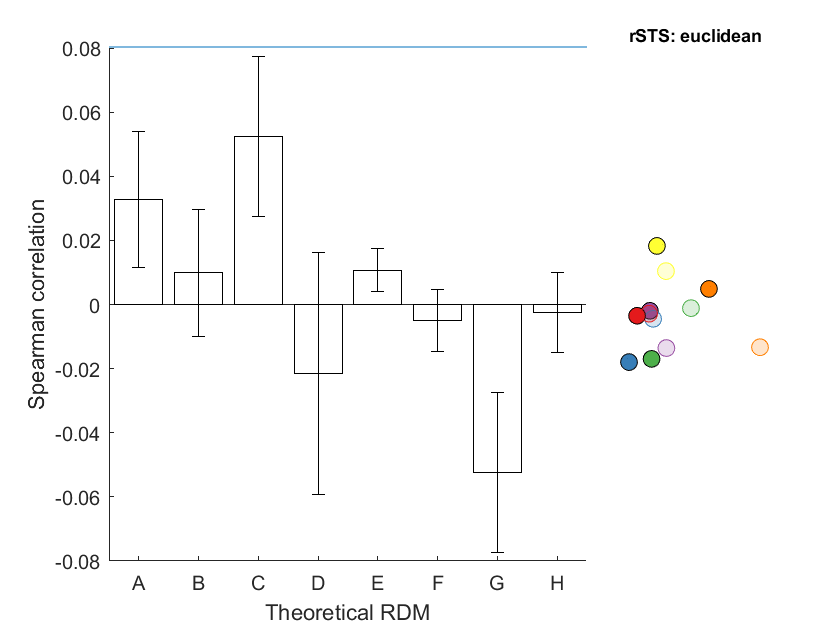

ROI = 'preSMA'

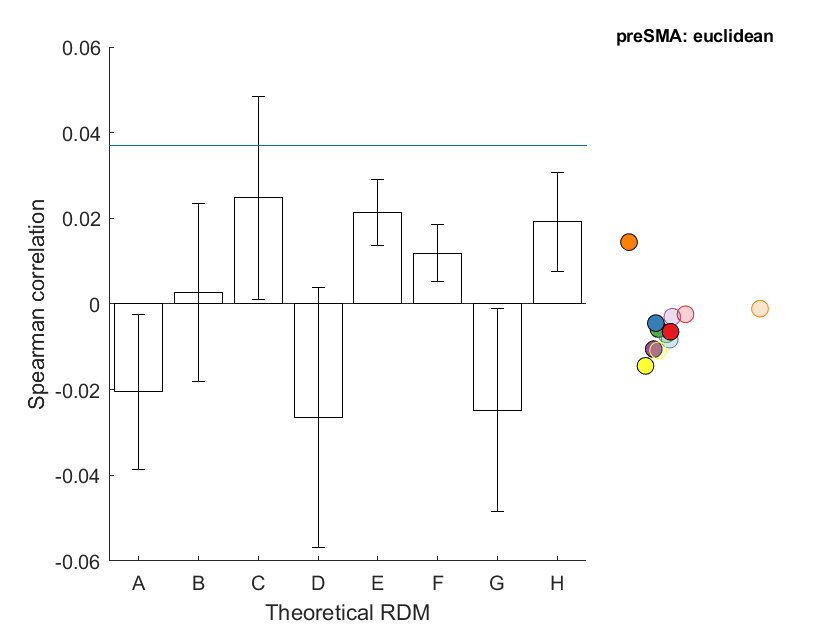

compareRDMs(project_params,which_subjects,'euclidean')

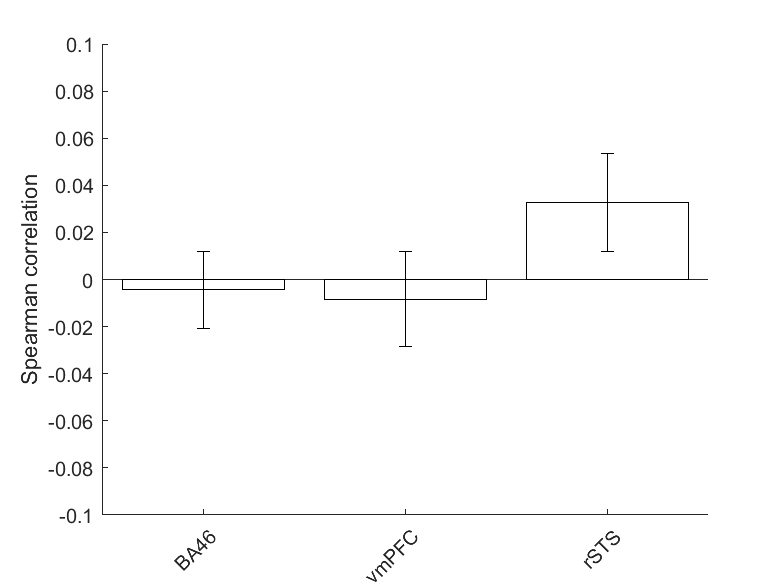

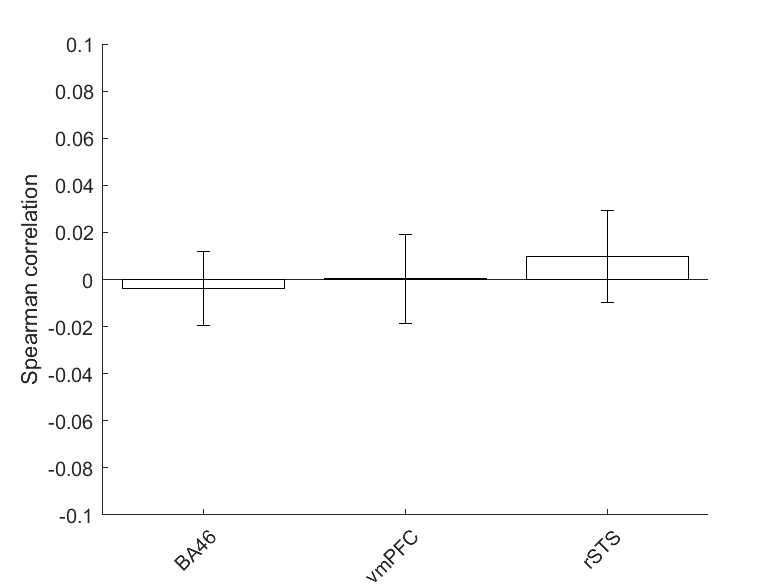

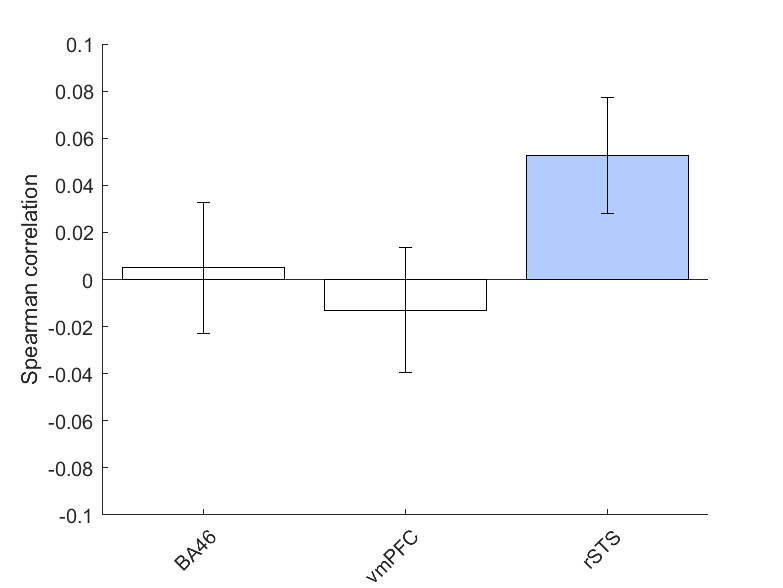

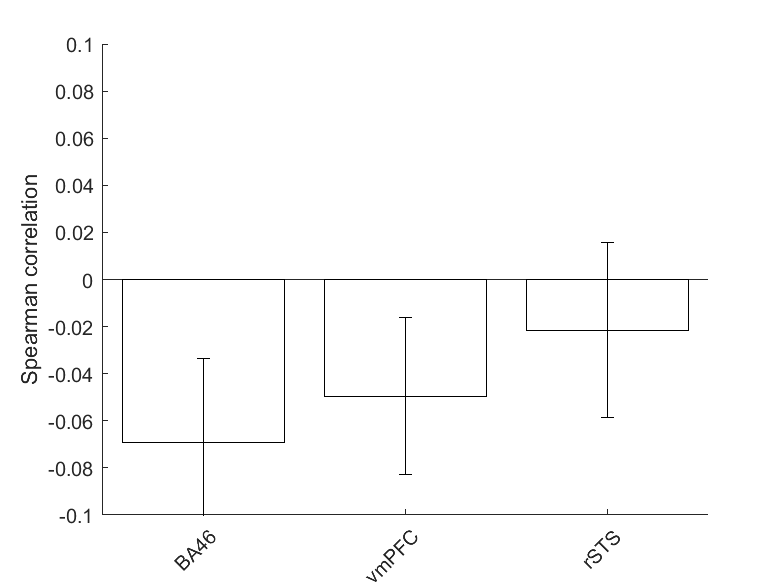

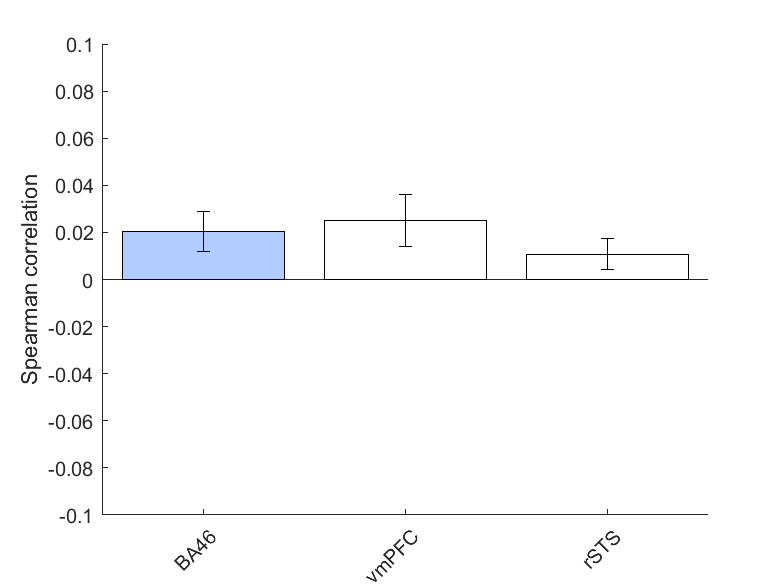

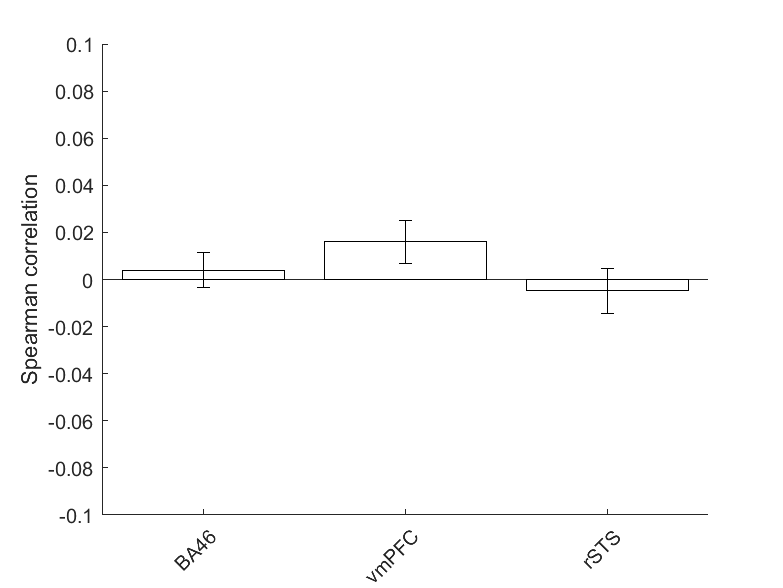

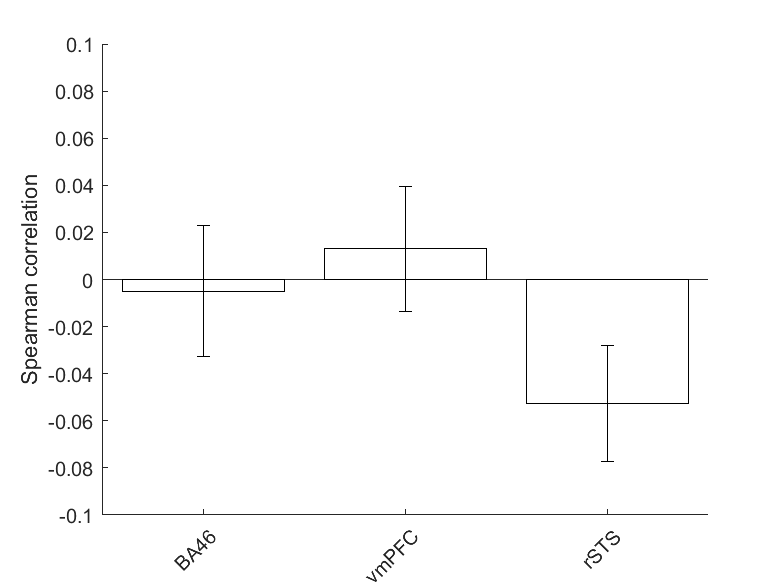

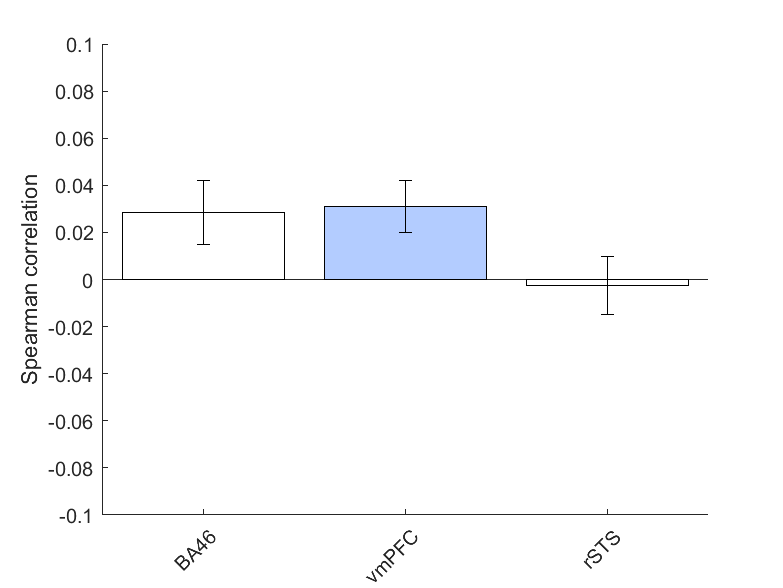

run("makeROIbasesRSAfigs.m")